# Proyecto de ciencia de los datos

## Universidad Autónoma del Estado de México

## CU UAEM Zumpango

## Ingeniería en Computación

## Ciencia de los Datos

## Integrantes:

#### Torres Escalona Alejandro

#### Parada Lopéz Adrian

#### Juárez Guzmán Verónica

## Profesor: 

#### Asdrúbal López Chau

#### Noviembre 2022

# Conjunto de datos.

Un cliente quiere adentrarse al mercado de dispositivos moviles diseñando sus propios dispositivos para asi competir contra las grandes compañias.

Pero no sabe como estimar el precio de los dispositivos que crea su empresa y los quiere estimar en base a las caracteristicas de un teléfono móvil.

# Preguntas 

- **¿Cuál es la cantidad mínima y maxima de miliamperios de una batería?**

#### Esta pregunta es del tipo "Descriptiva" ya que esta enfocada en resumir una característica

#### El motivo de esta pregunta es interesante para nuestro cliente, debido a que el está creando teléfonos móviles y debe tener en cuenta una de las características más importantes que es la autonomía del teléfono ya que eso dependerá los demás componentes y la cantidad de energía que brindará después de la carga.

#### Lo que se aplicará para contestar esta pregunta será contar los datos, y tomar el valor mínimo y máximo entre todos ellos 

     2. ¿**Por qué en algunos celulares les dura más la batería que en otros?**

#### Pregunta de tipo"Inferencia"

#### Esta pregunta genera mucho interés en los consumidores ya que buscan una gran autonomía al momento de adquirir un dispositivo móvil 

#### La respuesta a esta pregunta depende de las características con las que cuenta el teléfono como el procesador, pantalla, etc.

#### Para responder a esta pregunta, se tomaran en cuenta los componentes más importantes de un móvil, se compara con otros conjuntos de datos de otras compañías 

    3.**¿Cuál es el promedio de miliamperios de una batería y el promedio de tamaño de pantalla?**

#### Pregunta del tipo “Descriptiva”

#### Esta pregunta Es interesante para el cliente ya que puede tener la capacitad promedio de batería y el tamaño de pantalla en un celular y eso servirá como datos para la creación de dispositivos móviles en el futuro y asi poder asumir cuanto de los  miliamperios y el tamaño de la pantalla en promedio de los dispositivos y asi generar una idea general de autonomia que pueden llegar a ofrecer los dispositivos. 

#### La capacitad de batería en un móvil es muy importante, ya que de este componente depende la autonomía durante el uso el mismo asi como tambien el de tamaño de pantalla.

#### Para responder esta pregunta se tomará en cuenta 1000 datos, se calculará el área en cm^2 de la pantalla y su promedio de miliampares y área de pantalla de los dispositivos.

    4.**¿Cuál es la relación entre la calidad de la cámara principal y frontal de un dispositivo móvil?**

#### Pregunta del tipo “Descriptiva”

#### Esta pregunta suele ser interesante para el cliente y la audiencia ya que hoy en día de las cámaras suelen ser herramienta primordial para los usuarios. Conocer la relación entre estas 2 variables ayudara en la construcción y mejora para los dispositivos móviles.

#### Para contestar estas preguntas, se recolecto los datos de ambas características y se realizó un histograma en el que se visualizarán los datos de forma gráfica y así dar una interpretación más clara al conjunto de datos y además calcular su  relación estadística por el método de Pearson.

    5.**¿Cuál es la tecnologia de red (3G y 4G) más presente entre los dispositivos?**

#### Pregunta del tipo “Descriptiva”

#### En la actualidad existen 3 tipos de tecnologías para red celular, en la cual comienza desde 3G y 4G. Siendo el último el más utilizado por los consumidores y sería bueno para nuestro cliente saber cuantos de sus dispositivos cuentan con este tipo de tecnología y ver si es conveniente invertir en esta y ver que dispositivos cuentan con los estandáres requeridos por los clientes, en este caso consideramos al 4G como el de mayor consumo en el mercado. 

#### Para contestar esta pregunta, se tomará en cuenta cada uno de los datos y saber cuantos cuentan con estas 2 redes. Visualmente se entregarán porcentajes para así ayudar a nuestro cliente en la toma de decisiones, además de la relación entre los parámetros calculada con chi cuadrada. 

# Análisis Exploratorio

## Dataset Telefonos 

D= readtable("test.csv");

## Sacamos valores minimos y maximo de los las caracteristicas más importantes de un celular 

%Porcentaje de bateria
Bateria = D.battery_power;
%Soporta 4g o no
Cuatro_g = D.four_g;
%RAM en megabytes
Ram = D.ram;
%soporta wifi o no
Wifi = D.wifi;
%bluetooth
Blue = D.blue;
%Cuenta con pantalla touch o no 
Touch = D.touch_screen;
%soporta dual sim o no
Dual_sim = D.dual_sim;
%Soporta 3G o no
Tres_g = D.three_g;
%camara frontal megapixeles
Frontal = D.fc;
%Camara principal megapixeles
Principal = D.pc;
%velocidad a la que el microprocesador ejecuta las instrucciones
Velocidad = D.clock_speed;
%Numero de nucleos del procesador
Nucleos = D.n_cores;
%Altura de la pantalla cm
Hgt = D.sc_h;
%Ancho de pantalla del móvil en cm
Wdt = D.sc_w;
%tiempo de bateria
Tiempo = D.talk_time;
%touch
Touch = D.touch_screen;


## sacamos minimos y maximos

%Bateria
[minB,maxB] = bounds(Bateria)

minB = 500

maxB = 1999

%Ram
[minR,maxR] = bounds(Ram)

minR = 263

maxR = 3989

%Camara frontal
[minCF,maxCF] = bounds(Frontal)

minCF = 0

maxCF = 19

%Camara Principal
[minCP,maxCP] = bounds(Principal)

minCP = 0

maxCP = 20

%Velocidad del procesador
[minVP,maxVP] = bounds(Velocidad)

minVP = 0.5000

maxVP = 3

%Numero de nucleos
[minNN,maxNN] = bounds(Nucleos)

minNN = 1

maxNN = 8

%Alto de la pantalla
[minAlP,maxAlP] = bounds(Hgt)

minAlP = 5

maxAlP = 19

%Ancho de la pantalla
[minAcP,maxAcP] = bounds(Wdt)

minAcP = 0

maxAcP = 18

## Calculamos moda

%bateria
mBateria = mode(Bateria)

mBateria = 1074

%Ram
mRam = mode(Ram)

mRam = 305

%Camara frontal
mFrontal = mode(Frontal)

mFrontal = 0

%camara principal
mPrincipal = mode(Principal)

mPrincipal = 16

%velocidad
mVelocidad = mode(Velocidad)

mVelocidad = 0.5000

%nucleos
mNucleos = mode(Nucleos)

mNucleos = 4

%alto pantalla
mAlto = mode(Hgt)

mAlto = 5

%ancho Pantalla
mAncho = mode(Wdt)

mAncho = 0


corr(Ram(:,1),Bateria(:,1),'type','Pearson')

ans = -0.0324


%Se calcula el área de las pantallas 
area=Hgt.*Wdt

area =     84
     0
   170
     0
   120
    70
    28
    14
    99
     0


%Se calcula el promedio de el área calculada de las pantallas
% y el promedio de la bateria
promP=mean(area)

promP = 72.8640

promBat=mean(Bateria)

promBat = 1.2485e+03


h= stem(Bateria,Ram)

h =   Stem with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
          BaseValue: 0
              XData: [1043 841 1807 1546 1434 1464 1718 833 1111 1520 1500 1343 900 1190 630 1846 1985 1042 1231 1488 968 529 1558 533 1037 1025 1858 980 644 1024 1981 1380 1557 1201 1074 1175 1280 1715 1165 567 1952 822 685 1388 1972 1411 1094 1653 … ]
              YData: [3476 3895 2396 3893 1773 3506 3873 1495 3485 651 3866 3911 439 992 2751 563 2083 2187 3902 2524 1357 3456 1641 2322 3862 557 2427 625 3836 854 2383 926 3048 824 874 1617 3309 1786 3128 2243 994 2749 793 324 366 1228 1413 2617 … ]

  Show 

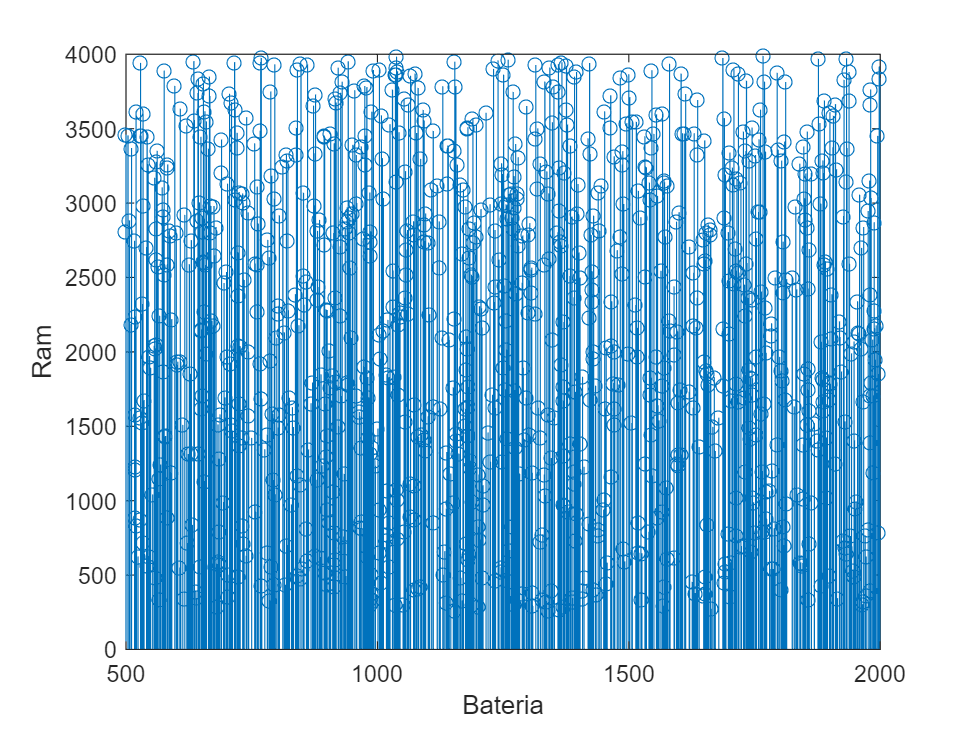

xlabel("Bateria")
ylabel("Ram")


cy=stem(Frontal,Principal)

cy =   Stem with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
          BaseValue: 0
              XData: [14 4 1 18 11 5 1 0 9 1 2 2 0 5 8 5 14 5 2 9 8 1 7 16 1 6 0 1 9 0 2 15 1 10 0 3 4 1 4 0 2 2 0 12 2 9 2 1 9 1 13 6 0 11 4 6 9 1 10 15 1 5 3 2 1 5 10 6 3 2 4 5 5 3 6 2 5 0 1 0 2 6 0 13 1 3 14 4 9 3 8 6 0 0 0 2 3 8 7 9 0 9 4 4 0 5 2 … ]
              YData: [16 12 4 20 18 9 3 2 19 20 6 6 3 15 9 7 17 15 3 20 17 5 10 18 6 16 1 5 10 0 13 16 11 20 6 8 5 16 11 1 10 7 15 19 14 17 5 15 20 6 14 10 3 14 10 15 11 2 14 17 4 6 5 7 15 6 14 20 5 20 16 6 14 5 19 4 12 0 4 1 8 16 3 16 11 17 20 20 16 … ]

  Show 

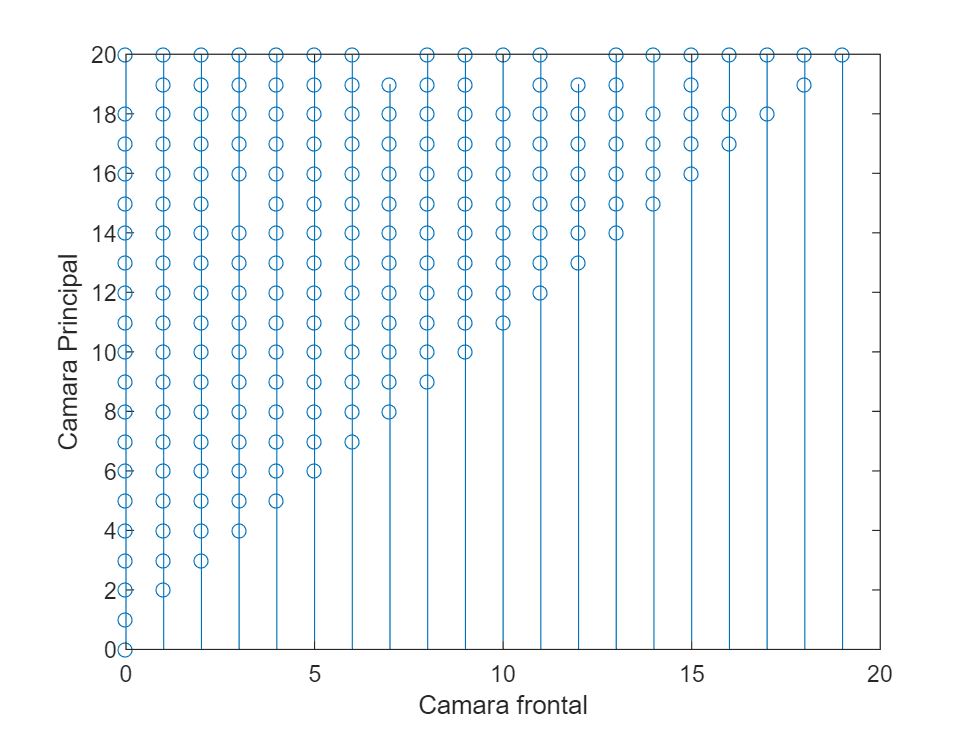

xlabel("Camara frontal")
ylabel("Camara Principal")

%porcentaje de celulares quienes soportan el 3G
valor = groupcounts(Tres_g)

valor =    244
   756


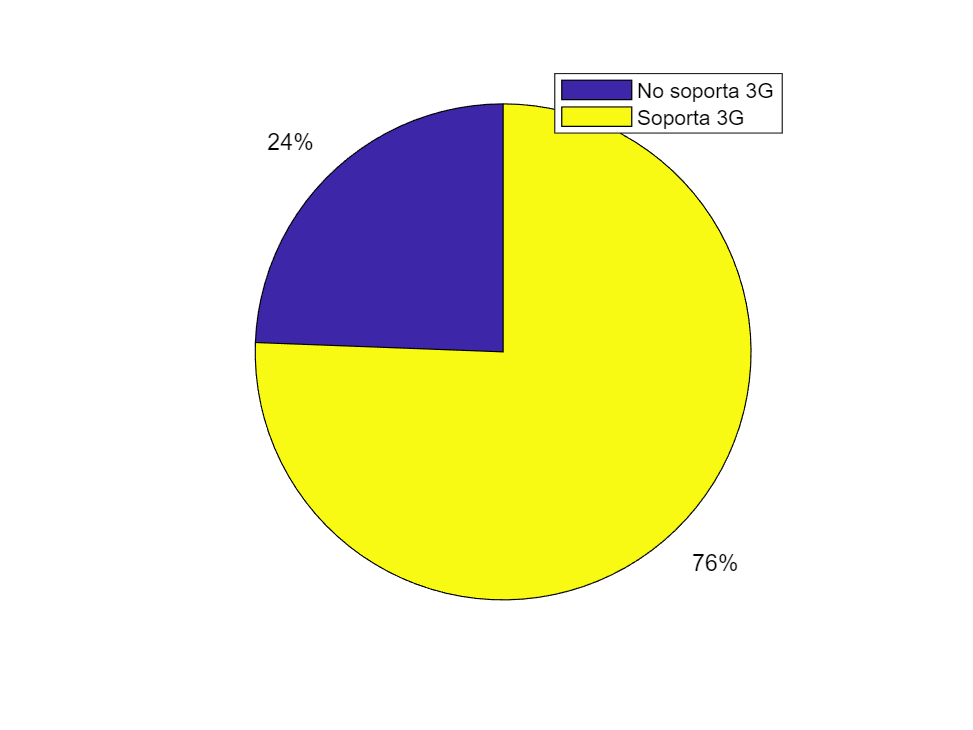

labels={'No soporta 3G', 'Soporta 3G'};
p=pie(valor);
%creacion de leyendas
lgd = legend(labels);

%porcentaje de celulares quienes soportan el 4G
valor = groupcounts(Cuatro_g)

valor =    513
   487



%porcentaje de celulares quienes soportan el Bluetooth
valor = groupcounts(Blue)

valor =    484
   516


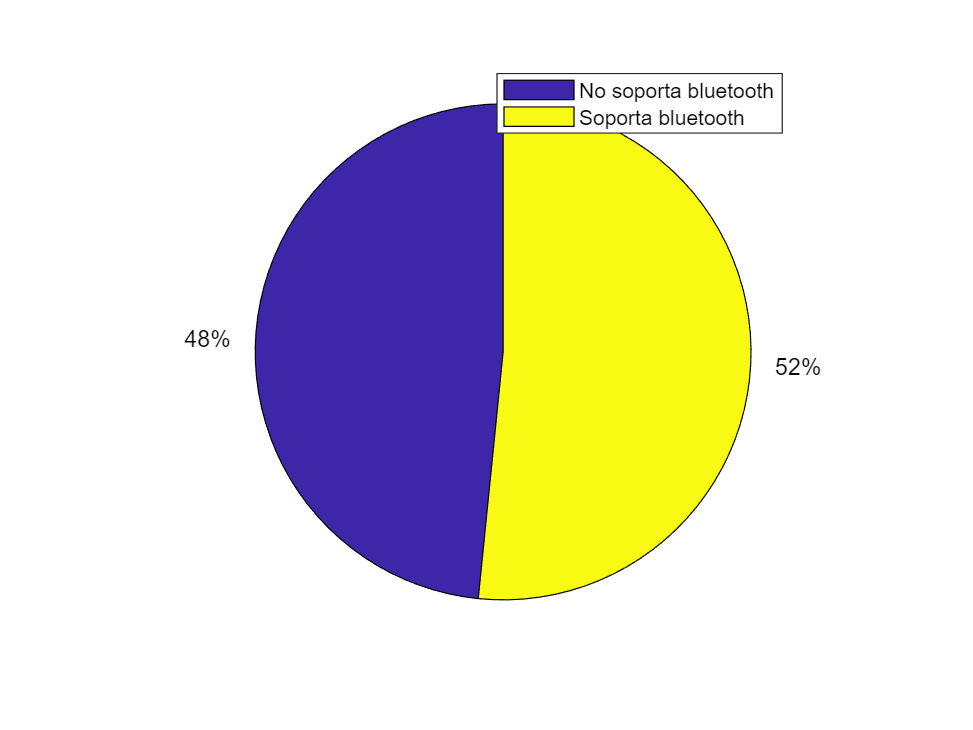

labels={'No soporta bluetooth', 'Soporta bluetooth'};
p=pie(valor);
%creacion de leyendas
lgd = legend(labels);

%porcentaje de celulares quienes soportan WiFi
valor = groupcounts(Wifi)

valor =    493
   507


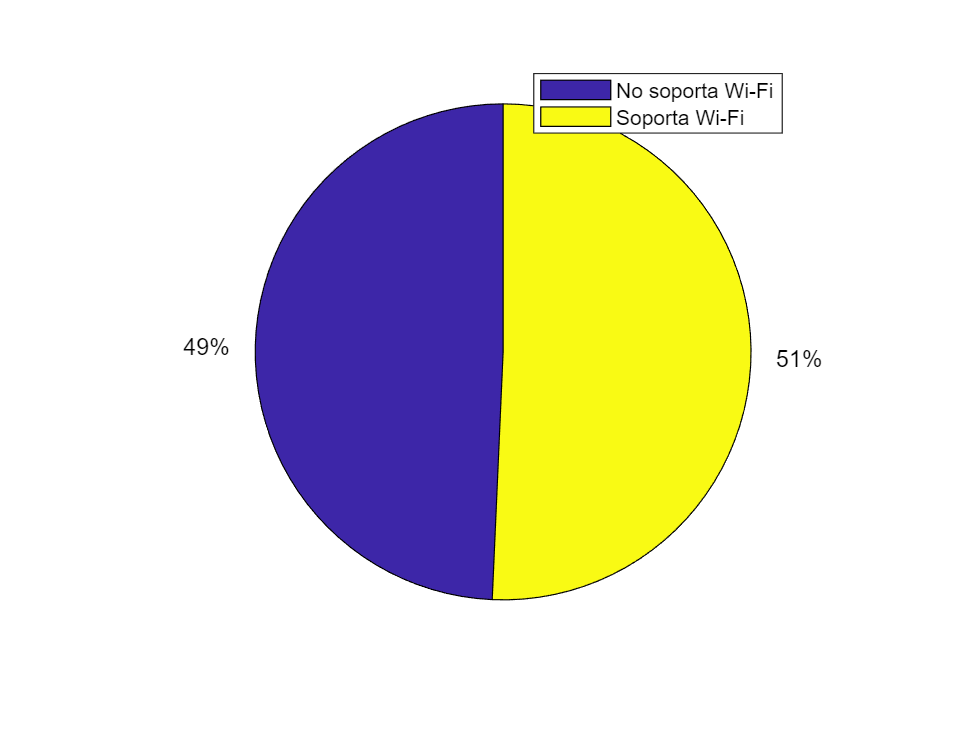

labels={'No soporta Wi-Fi', 'Soporta Wi-Fi'};
p=pie(valor);
%creacion de leyendas
lgd = legend(labels);




%relacion chi cuadrada
rel=chi2cdf(Cuatro_g, Tres_g)

rel =     1.0000
    0.6827
    1.0000
    0.6827
    0.6827
    0.6827
    1.0000
    1.0000
    0.6827
         0


Aplicar este tipo de análisis

# Análisis de los datos

%1.Bateria
[minB,maxB] = bounds(Bateria)

minB = 500

maxB = 1999

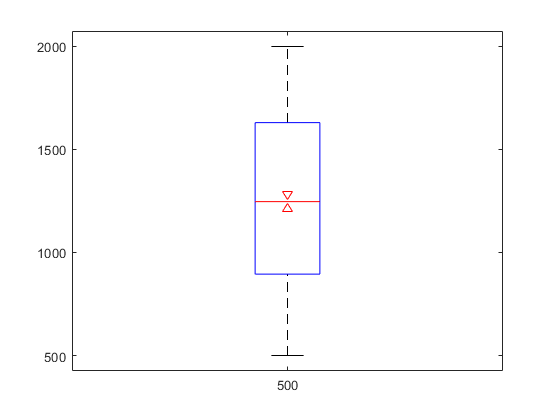

boxplot(Bateria,minB,"Notch","marker")

%Bateria minima
BateriaMinima=minB

BateriaMinima = 500

%correlacion entre coeficientes
[Ba, Ra] = corrcoef(Bateria,Ram)

Ba =     1.0000   -0.0324
   -0.0324    1.0000


Ra =     1.0000    0.3066
    0.3066    1.0000


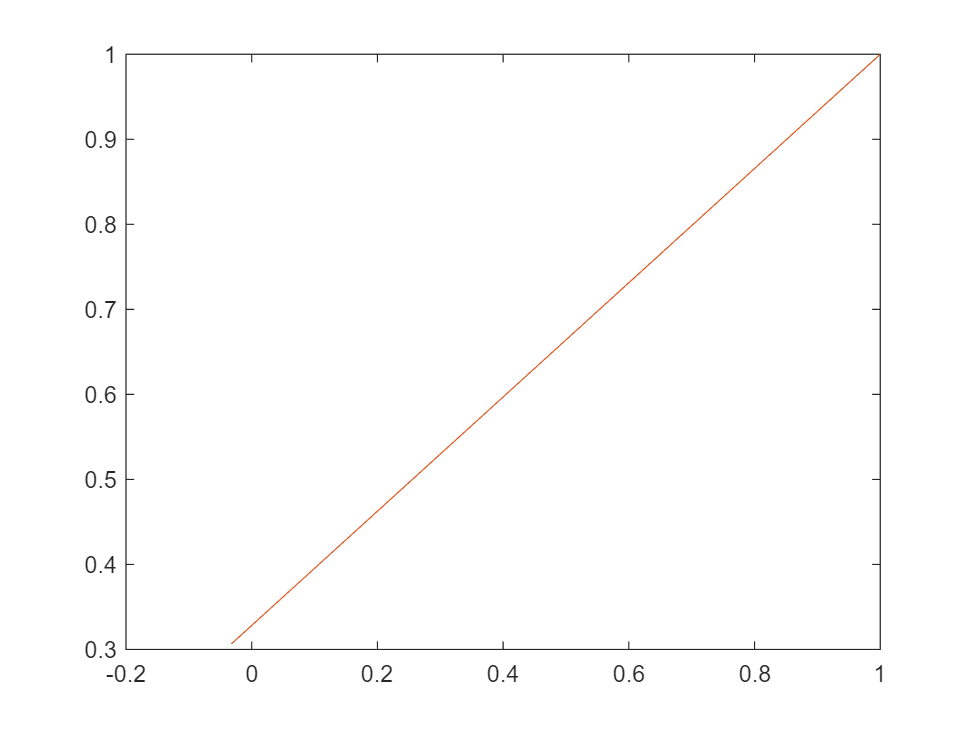

plot(Ba,Ra)

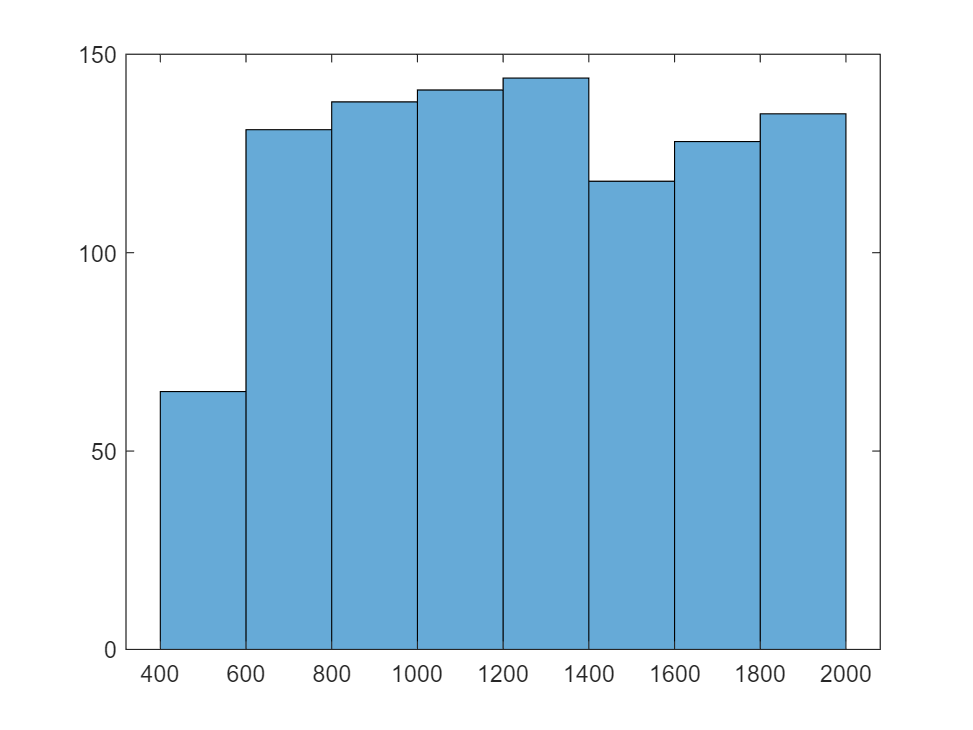

h =   Histogram with properties:

             Data: [1000×1 double]
           Values: [65 131 138 141 144 118 128 135]
          NumBins: 8
         BinEdges: [400 600 800 1000 1200 1400 1600 1800 2000]
         BinWidth: 200
        BinLimits: [400 2000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


h=histogram(Bateria)


%Se calcula el área de las pantallas 
area=Hgt.*Wdt;
%Se calcula el promedio de el área calculada de las pantallas
% y el promedio de la bateria
promP=mean(area)

promP = 72.8640

promBat=mean(Bateria)

promBat = 1.2485e+03




%correlacion entre coeficientes
[Pr, Fr] = corrcoef(Principal,Frontal)

Pr =     1.0000    0.6593
    0.6593    1.0000


Fr =     1.0000    0.0000
    0.0000    1.0000


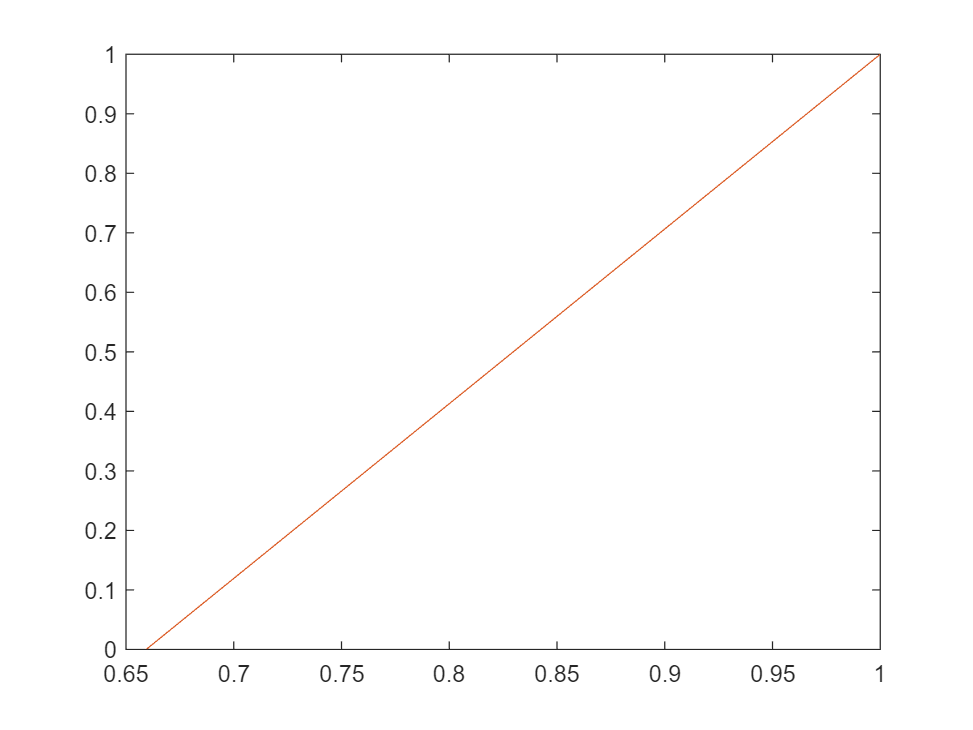

plot(Pr, Fr)

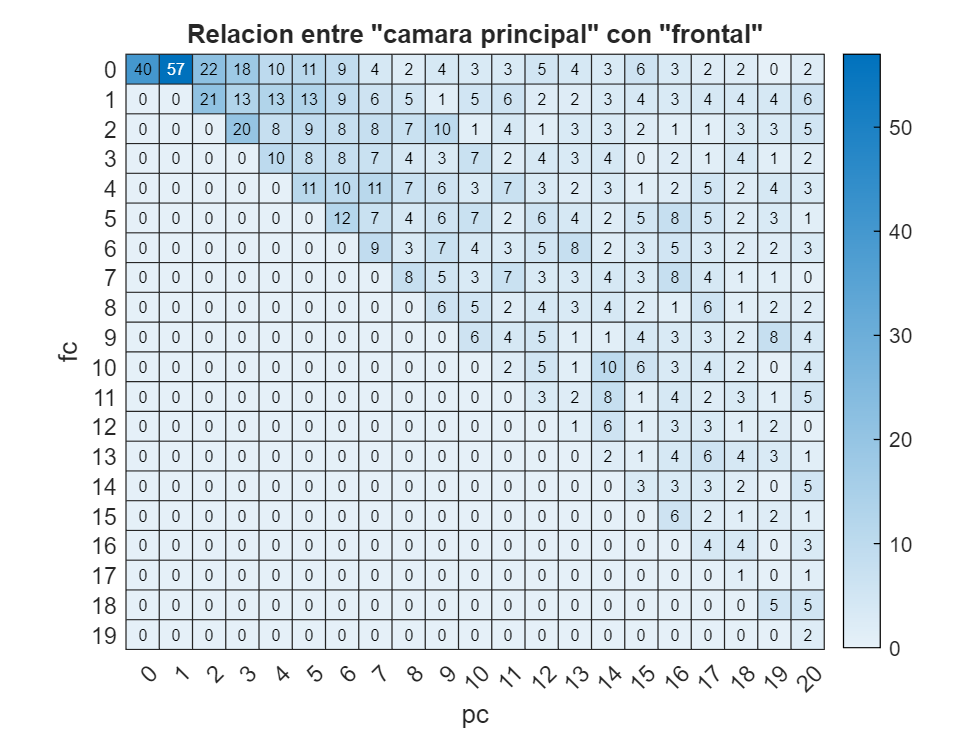

h =   HeatmapChart (Relacion entre "camara principal" con "frontal") with properties:

      SourceTable: [1000×21 table]
        XVariable: 'pc'
        YVariable: 'fc'
    ColorVariable: ''
      ColorMethod: 'count'

  Show all properties


h=  heatmap(D, "pc","fc");
h.Title='Relacion entre "camara principal" con "frontal"'

[tabla, chi2, p]= crosstab(D.fc,D.pc)

tabla =     40    57    22    18    10    11     9     4     2     4     3     3     5     4     3     6     3     2     2     0     2
     0     0    21    13    13    13     9     6     5     1     5     6     2     2     3     4     3     4     4     4     6
     0     0     0    20     8     9     8     8     7    10     1     4     1     3     3     2     1     1     3     3     5
     0     0     0     0    10     8     8     7     4     3     7     2     4     3     4     0     2     1     4     1     2
     0     0     0     0     0    11    10    11     7     6     3     7     3     2     3     1     2     5     2     4     3
     0     0     0     0     0     0    12     7     4     6     7     2     6     4     2     5     8     5     2     3     1
     0     0     0     0     0     0     0     9     3     7     4     3     5     8     2     3     5     3     2     2     3
     0     0     0     0     0     0     0     0     8     5     3     7     3     3     4     3     8 

chi2 = 1.5526e+03

p = 3.0386e-141

c=categorical(Cuatro_g,[0 1],{'0','1'})

c = 1000×1 categorical array
     0 
     1 
     0 
     1 
     1 
     1 
     0 
     0 
     1 
     0 
     0 
     1 
     0 
     0 
     1 
     1 
     1 
     1 
     1 
     0 
     1 
     0 
     0 
     0 
     0 
     1 
     0 
     0 
     0 
     1 


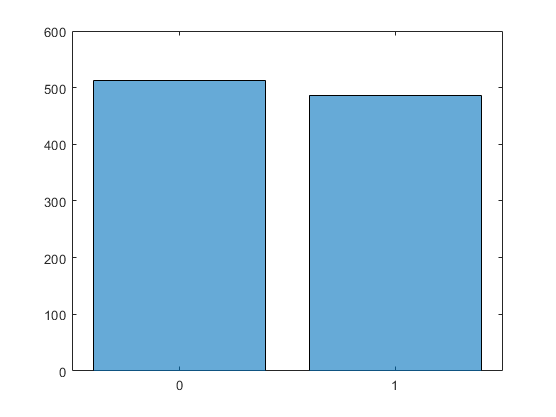

t =   Histogram with properties:

              Data: [1000×1 categorical]
            Values: [513 487]
    NumDisplayBins: 2
        Categories: {'0'  '1'}
      DisplayOrder: 'data'
     Normalization: 'count'
      DisplayStyle: 'bar'
         FaceColor: 'auto'
         EdgeColor: [0 0 0]

  Show all properties


t=histogram(c,'BarWidth',0.8)

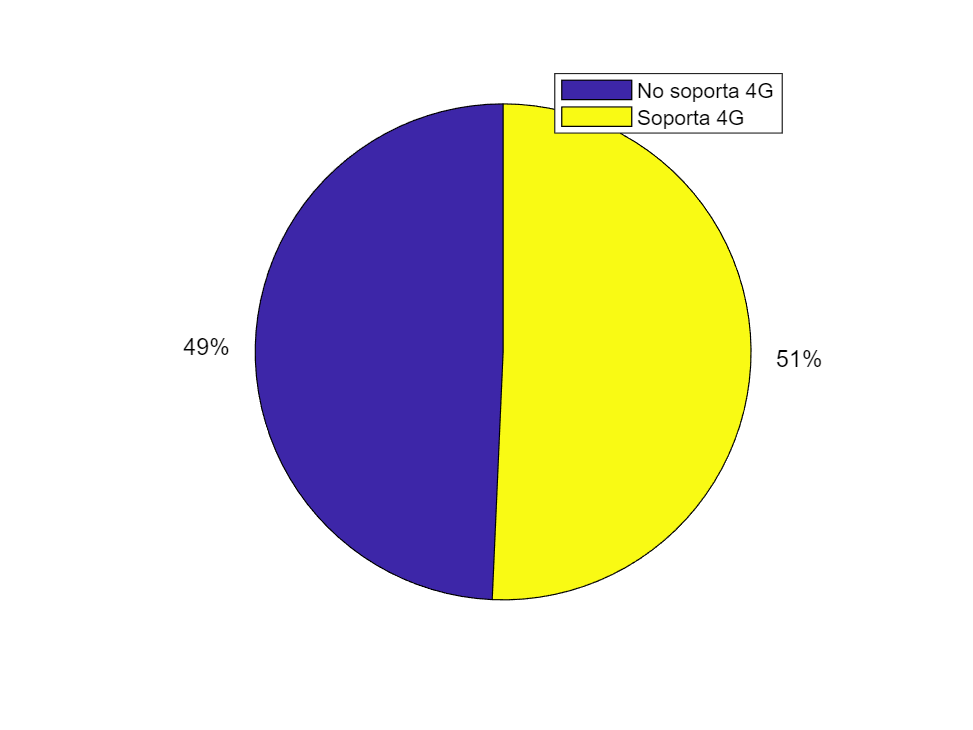

labels={'No soporta 4G', 'Soporta 4G'};
p=pie(valor);
%creacion de leyendas
lgd = legend(labels);


%Histograma bateria
stdHeight = std(Bateria)

stdHeight = 432.4582

x = linspace(500,2000)

x = 1.0e+03 *

    0.5000    0.5152    0.5303    0.5455    0.5606    0.5758    0.5909    0.6061    0.6212    0.6364    0.6515    0.6667    0.6818    0.6970    0.7121    0.7273    0.7424    0.7576    0.7727    0.7879    0.8030    0.8182    0.8333    0.8485    0.8636    0.8788    0.8939    0.9091    0.9242    0.9394    0.9545    0.9697    0.9848    1.0000    1.0152    1.0303    1.0455    1.0606    1.0758    1.0909    1.1061    1.1212    1.1364    1.1515    1.1667    1.1818    1.1970    1.2121    1.2273    1.2424


pdfHeight = normpdf(x,promBat,stdHeight)

pdfHeight = 1.0e-03 *

    0.2063    0.2190    0.2323    0.2461    0.2603    0.2751    0.2903    0.3060    0.3222    0.3387    0.3558    0.3732    0.3909    0.4090    0.4275    0.4462    0.4651    0.4843    0.5037    0.5231    0.5427    0.5623    0.5819    0.6014    0.6208    0.6401    0.6592    0.6780    0.6964    0.7145    0.7322    0.7494    0.7660    0.7821    0.7975    0.8122    0.8262    0.8394    0.8518    0.8632    0.8738    0.8834    0.8920    0.8996    0.9061    0.9116    0.9160    0.9192    0.9214    0.9224


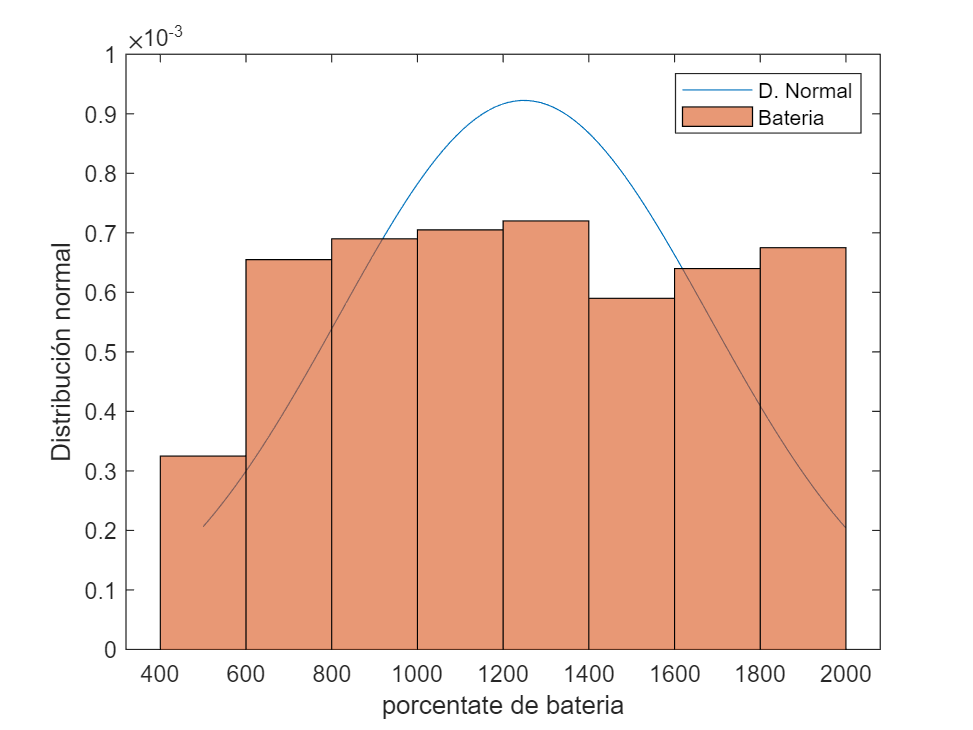

plot(x,pdfHeight)
hold on
histogram(Bateria,"Normalization","pdf")
hold off
xlabel("porcentate de bateria")
ylabel("Distribución normal")
%Probabilidad de que la linea caiga en los intervalos
legend("D. Normal","Bateria")

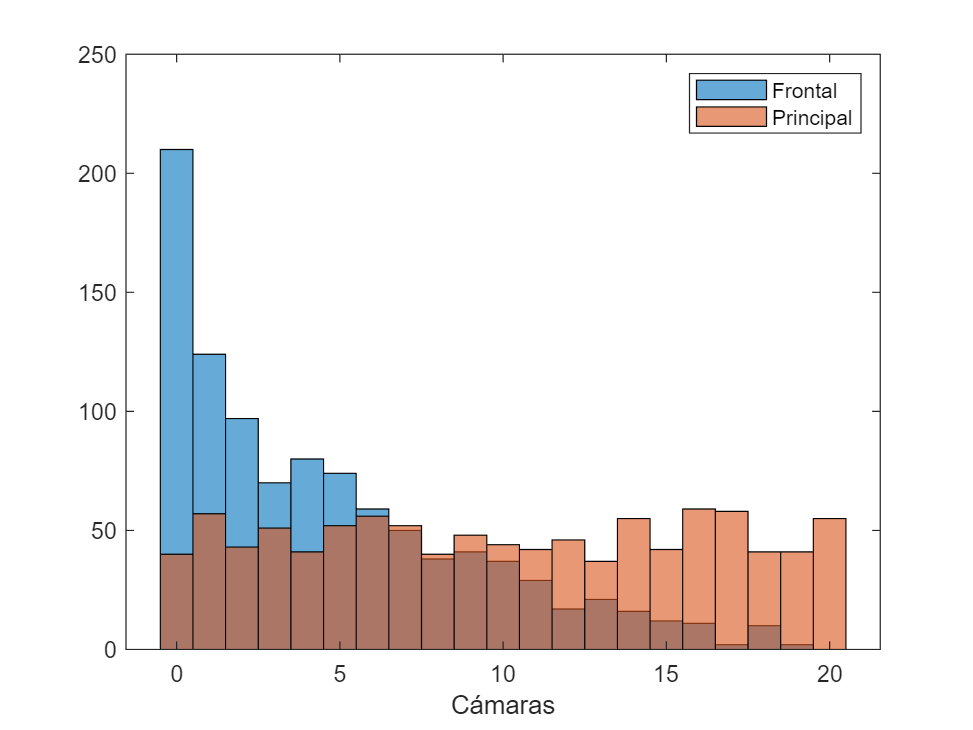


%Histograma cámaras
histogram(Frontal)
hold on
histogram(Principal)
hold off
xlabel("Cámaras")
legend("Frontal","Principal")

promFron=mean(Frontal)

promFron = 4.5930

promPr=mean(Principal)

promPr = 10.0540

%correlacion fuerte positiva (si uno aumenta el otro tambien)
corr(Frontal(:,1),Principal(:,1),'type','Pearson')

ans = 0.6593

%h0=No existe una  relacion entre los dispositivos con red 3G y 4G
%h1= Existe relacion entre los dispositivos con red 3G y 4G
% valor de p=1.333e-68 se rechaza h0 (asociacion significativa)
%Si P <0.05 se afirma la hipotesis, >0.05 se rechaza 
[tabla, chi2, p]=crosstab(Tres_g,Cuatro_g)

tabla =    244     0
   269   487


chi2 = 306.3936

p = 1.3331e-68

Aplicar los métodos necesarios.

Limpieza de los datos.

# Hallazgos

#### Pregunta 1

Se responde muy concretamente ya que solo buscamos el valor mínimo y máximo de todos datos.

El valor máximo que se encontro es de 1999 miliamperios y el valor minimo es de 500 miliampares 

#### Pregunta 2

No se puede responder debido a que la duración de la batería entre celulares ya que dependen de los componentes, autonomía, modelos, y el fabricante. Los datos no fueron los óptimos para darles una interpretación clara y por ello no se pudo dar una respuesta concreta a la pregunta. 

#### Pregunta 3

Se respondió calculando la media de todos los datos de los miliamperios de la batería  y del área de la pantalla calculada en centimetros cuadrados. 

Se obtuvieron los resultados de 1.2485e+03 para el promedio de miliamperios de batería y un área promedio de 80.2570 cm^2.

#### Pregunta 4

En la relació estadística calculada por Pearson se optuvo un valor de 0.6593 dando asi una correlación fuerte positiva en la que si la calidad de una cámara aumenta el de la otra tambien.

#### Pregunta 5

Se obtuvieron el porcentajes de celulares que cuentan con 3G y con 4G se obtuvo que un 76% (756) de los dispositivos cuenta con 3G y 24% (244) restante no, en el caso del 4G el 51% (513) cuenta con esta tecnologia y el 49% (487) restante no.  

Para el analisis estadistico se plantearon las hipótesis de:

h0=No existe una  relacion entre los dispositivos con red 3G y 4G

h1= Existe relacion entre los dispositivos con red 3G y 4G

valor de p=1.333e-68 se rechaza h0 (asociacion significativa)

Con base en los resultados de los análisis, describir detalladamente los hallazgos encontrados. Justificar con los modelos empleados.

# Conclusiones

Para este analisis no se utilizaron todas las variables incluidas en el Data set, solo se utilizaron algunas con las que se considero que se podian optener mayor informacion para interpretarla. Con este analisis pudimos ver la relacion de varias caracteristicas de un dispositivo como lo es un teléfono celular, como lo fueron la bateria, el tipo de red con la que cuenta, los megapixeles de las cámaras y  el tamaño de pantalla todo esto para darle una interpretación clara a el conjunto de datos y con ello contestar las preguntas planteadas al principio de la elaboracion de este proyecto.

Ademas de utilizar varias heramientras de MATLAB con las que se pudo experimentar y probar con diferentes variables para obtener varios resultados y nos ayudo dar una mejor interpretación y tratamiento a la información.

Con la informacion obtenida con este analisis se pudieron detectar algunas las propiedades con la que cuentan los productos y algunas deficiencias entre estos diferentes productos del cliente. Con esto se espera ayudar a la toma de decisiones para mejorarlos como lo podria ser el mejoramiento de la camara frontal y el imprementar una red 4G a más dispositivos de los que ya cuenta con ella para asi tener un mejor desempeño dentro del mercado.